# **Metabolic visualisation in ReconMap (Minerva) **

## Authors: Alberto Noronha, Ines Thiele and Ronan M.T. Fleming

## **Affiliation: **Luxembourg Centre for Systems Biomedicine, University of Luxembourg, Luxembourg.

## Reviewer(s): 

## INTRODUCTION

The visualisation of metabolic pathways is an essential tool to understand the biological meaning underlying COBRA metabolic models. This would allow the user to visualise what can not be appreciated at first sight by directly looking to the model outputs. Here we present a visualisation through ReconMap [[noronha_reconmap:_2017](#LyXCite-noronha_reconmap__2017)], a virtual visualisation of human metabolism derived from Recon 2.04 [[thiele_community-driven_2013](#LyXCite-thiele_community_driven_2013)]. Diverse models can be found in the website  [http://vmh.uni.lu.](http://vmh.uni.lu.) 

## **EQUIPMENT SETUP**

In order to access remotely to ReconMap, the user has to be registered. To obtain your credentials, you must access the ADMIN area and request an account.  To access ReconMap follow the link:  [http://vmh.uni.lu.](http://vmh.uni.lu.) 

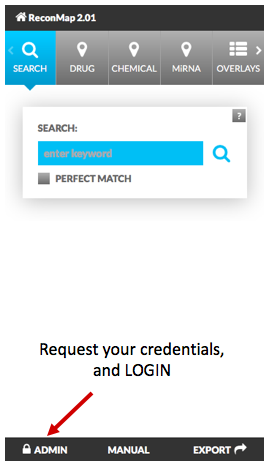     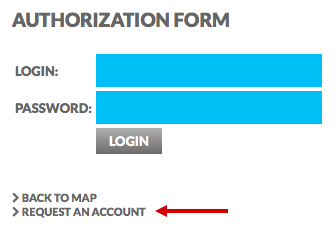

Then, use your credentials to remotely access to [http://vmh.uni.lu.](http://vmh.uni.lu.)  

load('minerva.mat')
minerva.minervaURL = 'http://vmh.uni.lu/minerva/galaxy.xhtml';
minerva.model = 'ReconMap-2.01'; 
if 0
    minerva.login = 'user_name';
    minerva.password = 'user_password';
else
    minerva.login = 'john';
    minerva.password = 'doe';
end

Initialise the Cobra Toolbox.

A specific solver might be required (depending on the analysis you want to realise in the COBRA model).

changeCobraSolver('gurobi','QP');


 > Gurobi interface added to MATLAB path.


changeCobraSolver('gurobi', 'LP');


 > Gurobi interface added to MATLAB path.


Load your generic metabolic model. Recon's most recent version "Recon2.04" can be freely downloaded from [http://vmh.uni.lu.](http://vmh.uni.lu.)  

model = readCbModel('Recon2.v04.mat')

model =                       S: [5063×7440 double]
                   mets: {5063×1 cell}
                      b: [5063×1 double]
                 csense: [5063×1 char]
                   rxns: {7440×1 cell}
                     lb: [7440×1 double]
                     ub: [7440×1 double]
                      c: [7440×1 double]
                 osense: -1
                  genes: {2140×1 cell}
                  rules: {7440×1 cell}
             metCharges: [5063×1 double]
            metFormulas: {5063×1 cell}
               metNames: {5063×1 cell}
              metHMDBID: {5063×1 cell}
         metInChIString: {5063×1 cell}
              metKEGGID: {5063×1 cell}
           metPubChemID: {5063×1 cell}
            description: 'Recon2.v04.mat'
                grRules: {7440×1 cell}
             rxnGeneMat: [7440×2140 double]
    rxnConfidenceScores: [7440×1 double]
               rxnNames: {7440×1 cell}
               rxnNotes: {7440×1 cell}
           rxnECNumbers: {7440×1 cell}
   

## **PROCEDURE**

**1. Overlay a flux distribution**

As an example of layout, we would like to see the the fluxes when maximizing ATP production  through complex V (ATP synthase) in the Electron Transport Chain. To do so, we use Flux Balance Analysis (FBA) and set as an objective function the reaction responsible of this process (`'ATPS4m'). `

`ChangeObjective `function, changes the objective function of a constraint-based model 

`optimizeCbModel `function solves a flux balance analysis problem.

formula = printRxnFormula(model, 'ATPS4m')

ATPS4m	4 h[c] + adp[m] + pi[m] 	->	3 h[m] + h2o[m] + atp[m] 


formula =     '4 h[c] + adp[m] + pi[m]  -> 3 h[m] + h2o[m] + atp[m] '


model_atp_production = model  % re-name the model to do not modify the original one.

model_atp_production =                       S: [5063×7440 double]
                   mets: {5063×1 cell}
                      b: [5063×1 double]
                 csense: [5063×1 char]
                   rxns: {7440×1 cell}
                     lb: [7440×1 double]
                     ub: [7440×1 double]
                      c: [7440×1 double]
                 osense: -1
                  genes: {2140×1 cell}
                  rules: {7440×1 cell}
             metCharges: [5063×1 double]
            metFormulas: {5063×1 cell}
               metNames: {5063×1 cell}
              metHMDBID: {5063×1 cell}
         metInChIString: {5063×1 cell}
              metKEGGID: {5063×1 cell}
           metPubChemID: {5063×1 cell}
            description: 'Recon2.v04.mat'
                grRules: {7440×1 cell}
             rxnGeneMat: [7440×2140 double]
    rxnConfidenceScores: [7440×1 double]
               rxnNames: {7440×1 cell}
               rxnNotes: {7440×1 cell}
           rxnECNumbers: {7

model_atp_production = changeObjective(model_atp_production, 'ATPS4m'); 
solution_atp_prod_max_regularised = optimizeCbModel(model_atp_production, 'max',1e-6);
solution_atp_prod_max_sparse = optimizeCbModel(model_atp_production, 'max','zero');

This reaction is expressed in the regularised but not in the sparse, yet both show up in the map!!!!!!!!!!!!!!!!!!!!!!

nnz(solution_atp_prod_max_regularised.v)
solution_atp_prod_max_regularised.v(strcmp(model.rxns,'r0603'))

nnz(solution_atp_prod_max_sparse.v)
solution_atp_prod_max_sparse.v(strcmp(model.rxns,'r0603'))

## ANTICIPATED RESULTS

`The buildFluxDistLayout `function, create a layout that is automatically sent to the ReconMap website. After this, you can visualise your layout in [http://vmh.uni.lu.](http://vmh.uni.lu.)  Use your credentials to log in as it is previously explained.  Select your input map (minerva.model) and go to "overlays" section to find your layout.   

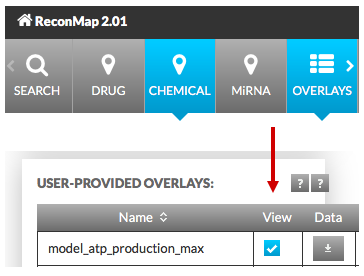

serverResponse = buildFluxDistLayout(minerva, model, solution_atp_production_max_regularised, 'atp_prod_max_regularised3',[],'#6617B5')

serverResponse =     [1]    'Overlay was sucessfully sent to ReconMap!'

serverResponse = buildFluxDistLayout(minerva, model, solution_atp_production_max_sparse, 'atp_prod_max_sparse4',[],'#6617B5')

serverResponse =     [1]    'Overlay was sucessfully sent to ReconMap!'

If everything is correctly defined you should get a structure with 2 values. If everything works fine, the output of this function should be:

`[1] 'Overlay was successfully sent to ReconMap!' `

 If there is any error, the message obtained will display:

`[0] 'Explanation of the obtained error' `

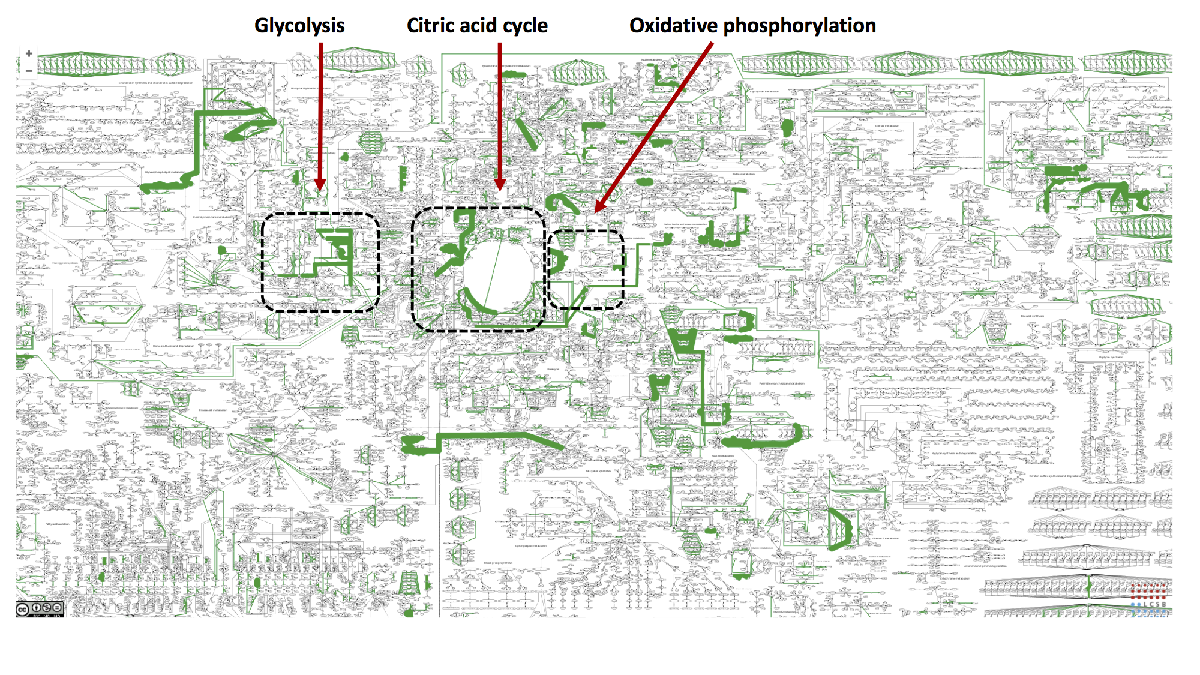

Note: If the "layout name" selected has been already given, an error might appear. Please, try to give a new layout name each time you run the code. 

`[0]    'ERROR. Layout with given identifier ("atp_productio…'`

**2. Overlay a SubSystem**

There is also the possibility to highlight a specific subSystems by using the function `generateSubsytemsLayout. A` subSystem is a group of metabolic reactions involved in the same metabolic pathway, such as glycolysis, Oxidative phosphorylation, citric acid cycle, etc.  Add the name of a specific subSystem you want to highlight from the COBRA model (see the example, TCA cycle), and the color reference. 

generateSubsytemsLayout(minerva, model, 'Citric acid cycle', '#6617B5');

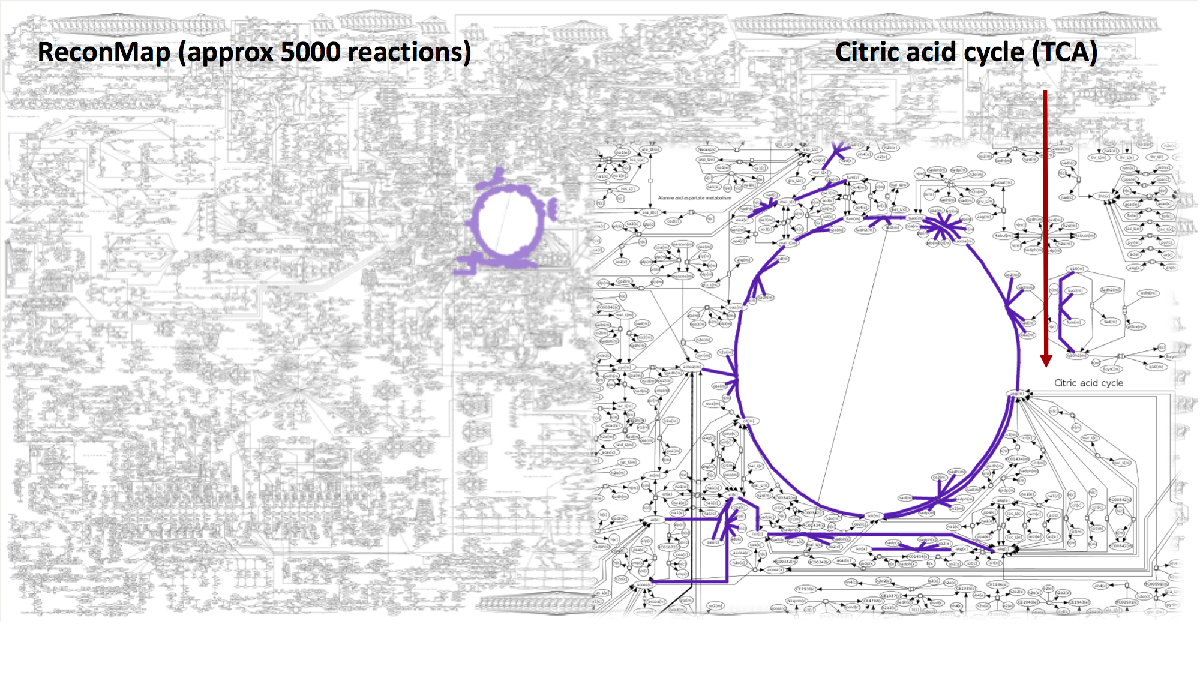

Alternatively, the user can generate a layout of all common subSystems between model and map using the function  `generateSubsystemLayouts. `

Note: every single layout can be observed individually, or merged with other layouts. Therefore, making possible the visualization of several layouts at the same time.

## REFERENCES: 

[1] Alberto Noronha, Anna Dröfn Daníelsdóttir, Piotr Gawron, Freyr Jóhannsson, Sofía Jónsdóttir, Sindri Jarlsson, Jón Pétur Gunnarsson, Sigurður Brynjólfsson, Reinhard Schneider, Ines Thiele, and Ronan M. T. Fleming. ReconMap: an interactive visualization of human metabolism. Bioinformatics , 33(4):605607, February 2017.

[2] Ines Thiele, Neil Swainston, Ronan M. T. Fleming, Andreas Hoppe, Swagatika Sahoo, Maike K. Aurich, Hulda Haraldsdottir, Monica L. Mo, Ottar Rolfsson, Miranda D. Stobbe, Stefan G. Thorleifsson, Rasmus Agren, Christian Bölling, Sergio Bordel, Arvind K. Chavali, Paul Dobson, Warwick B. Dunn, Lukas Endler, David Hala, Michael Hucka, Duncan Hull, Daniel Jameson, Neema Jamshidi, Jon J. Jonsson, Nick Juty, Sarah Keating, Intawat Nookaew, Nicolas Le Novère, Naglis Malys, Alexander Mazein, Jason A. Papin, Nathan D. Price, Evgeni Selkov Sr, Martin I. Sigurdsson, Evangelos Simeonidis, Nikolaus Sonnenschein, Kieran Smallbone, Anatoly Sorokin, Johannes H. G. M. van Beek, Dieter Weichart, Igor Goryanin, Jens Nielsen, Hans V. Westerho, Douglas B. Kell, Pedro Mendes, and Bernhard Ø Palsson. A community-driven global reconstruction of human metabolism. 5 Nat Biotech , 31(5):419425, May 2013.